# Mono Lake water-balance model in MATLAB

In this activity you will write a MATLAB script to solve the Mono Lake water balance equation over time using the Euler method.

The model uses data from Peter Vorster's 1985 MA thesis described in section 3 below to constrain flows and the lake's geometry. Resutls are compared to lake elevation data compiled by the Mono Lake Comission. All of the spreadsheets containing these data should be saved in the same folder as your MATLAB script.

## Learning Goals

After completing this activity, you should be able to:

- Implement a numerical simulation of a water balance equation in MATLAB using the forward Euler method

- Design and construct a dynamic model of a natural hydrologic system using MATLAB scripting.

Key MATLAB functions and concepts introduced

- readmatrix

- logical indexing (using logicals ==, >=, <= and boolean &)

- interp1

- for loop

- legend

- mean

- quantile

## Lake Model Development

We'll start our script with a block of comments that describe the model and restrictive assumptions. **Missing commands or comments are marked with ****

    1.    Start your model script with comments explaining the model and its derivation

% Script to solve Mono Lake water balance model using forward Euler method.
% **The model describes...**
% **The equations were derived assuming...**
% **The data are from...**


    2.    Next we'll define parameters that are model specific and we may wish to change later.

% Define model specific values **Add definitions and comments with units for each parameter**

% We will use a constant time interval, dt (start with dt = 1 (year)).
dt = 1;

% Set starting time - ts (start with a model running from 1937 to 1983).
ts = 1937;

% Set ending time - tf (start with a model running from 1937 to 1983).
tf = 1983;

% Define a vector of time steps, t, for the model using first:interval:last syntax.
% Your model should run from ts to tf in steps of dt.
t = ts:dt:tf;


    3.    Then we'll read in data sets from Peter Vorster's thesis (1937-1983) and the Mono Lake Commision (MLC) (Lake levels from 1851-2017).

% Read in Vorster measured data using xlsread
    % All data are in cells B2:B48, The individal sheets contain the following data:
    % 1. Elevation [feet above msl], 2. Volume [Acre-Feet], 3. Area [Acres],
    % 4. Gauged stream [flow, Acre-Feet per Year], 5. Diversion [flow, Acre-Feet per Year]
    % 6. Ungauged [flow, Acre-Feet per Year], 7. Precipitation [rate, Feet per Year],
    % 8. Evaporation [rate, Feet per Year].

% read in data sets that we will use in the model.
    % The MATLAB code is given for the Gauged Stream flows (Q_gauged).
    Q_gauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Gauged stream', 'datarange','B2:B48');
    
    % ** Copy and modify for Diversion (Q_diversion), Unguaged (Q_ungauged)
    % streams, Precipitation (P_rate) and Evaporation (E_rate) rates.**
    Q_diversion = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Diversion', 'datarange','B2:B48');
    Q_ungauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Ungauged', 'datarange','B2:B48');
    P_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Precipitation', 'datarange','B2:B48');
    E_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Evaporation', 'datarange','B2:B48');

% Read in the Vorster lake survey data for volume conversions
    % Columns: 1. Volume (acre-ft), 2. Area (acre), 3. Elevation (ft above msl)
    % We'll read in all the numeric values so we can use this simple syntax
    Survey = readmatrix('Mono_Lake_Survey.xlsx');

% Read in the historic lake elevation data from the MLC (years in column A, elevations in B,
% all rows 2 to 167. Use xlsread to read appropriate columns into 2 variables: 
% YR_measured and Z_measured
YR_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'A2:A169');
Z_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'B2:B169');

% The MLC data are reported in calendar years, while Vorster data are
% reported in water years. ** add one to the MLC YR_measured to make the
% data sets conistent**
YR_measured = YR_measured + 1;


% Set the inital lake elevation (Z0) based on starting year
% we'll use logical indexing, which is very handy for this sort of task.
Z0 = Z_measured(YR_measured==ts); % feet above msl

% We'll use the lake survey data and linear interpolation to estimate the
% initial water volume (V0) from the initial lake elevation (Z0)
V0 = interp1(Survey(:,3), Survey(:,1), Z0);


    4.    Now define empty variables to store our numerical solutions and set the initial condition.

% ** Define variables to store your results: V_Model for Lake Volume and
% Z_Model for elevation at each time step. Use zeros and size to make a vector of
% zeros the same size as your time vector.**
V_Model = zeros (size(t));
Z_Model = zeros (size(t));

% ** Set the first value of V_Model and Z_Model equal to the intial condition for each variable (V0, Z0).**
V_Model(1) = V0;
Z_Model(1) = Z0;

    5.    Now we'll solve the problem first using the forward Euler method and plot the results

% Forward Euler solution. Our solution will step through the time steps calculating
% the next solution from the current solution.

% **define a for loop that steps from n=1 to one less than the number of time steps.**
for n = 1:length(t)-1
    % Calculations within loop:

    
    % Estimate area (acres) from volume (acre-ft) using linear interpolation
    % We'll interpolate the area based on our modeled volume using interp1
    LakeArea = interp1(Survey(:,1), Survey(:,2), V_Model(n));
    
    % Estimate evaporation **and precipitation** fluxes from lake area and rates
    Q_Evap = E_rate(n) .* LakeArea;
    Q_Precip = P_rate(n) .* LakeArea;
    
    % ** Add equation for Euler method. Store results in the next element (n+1) of V_Model**
    V_Model(n+1) = V_Model(n) + ((Q_gauged(n)+Q_Precip+Q_ungauged(n)-Q_Evap-Q_diversion(n)) .* dt);
    
    % **Estimate model lake elevation (ft above msl) from model volume (acre-ft) for next
    % time step using linear interpolation (interp 1) and Vorster survey data.**
    Z_Model(n+1) = interp1(Survey(:,1), Survey(:,3), V_Model(n+1));
    
% **define the end of your loop with 'end'**
end
% **plot model results using blue line and circle**
figure
plot (t,Z_Model,'bo-')
hold on

    6.    We'll add the historic data to our plot.

% **First hold the plot.**

% Then plot the data with black stars. Note that we only want the data
% from years >=ts and <=tf. Use these two logical statements linked by a boolean &
% to slect these values from the Z_measured varible and plot them against t.**

plot(t, Z_measured(YR_measured>=ts & YR_measured<=tf), 'pentagram', 'Color', [0 0 0])

    7.    We'll complete our plot by adding axis labels, a title, and a legend

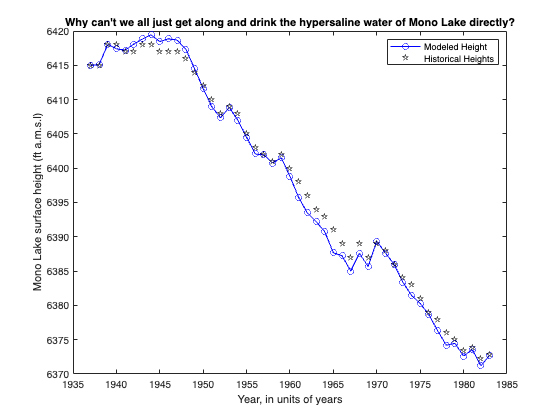

% **add axis labels**
xlabel ("Year, in units of years")
ylabel ("Mono Lake surface height (ft a.m.s.l)")

% **add legend('series 1', 'series 2')**
legend ("Modeled Height", "Historical Heights")
title("Why can't we all just get along and drink the hypersaline water of Mono Lake directly?")

hold off

## Calculating Model Error

We can calculate the difference between our model and the observations at each time step using elementwise calculations.

% **Calculate the error (model - data). You'll need to use logical indexing again to
% return the appropriate data vector.**
Error=Z_Model-Z_measured(YR_measured>=ts & YR_measured<=tf)'

Error =          0    0.0641    0.0345   -0.5865    0.2007    1.0795    0.8343    1.4277    1.4587    1.8647    1.6687    1.3451    0.5235   -0.3825   -1.0723   -0.6439   -0.1428   -1.0135   -0.4859   -0.9276   -0.0590   -0.2524   -0.4794   -1.2064   -2.2724   -2.5289   -1.7708   -2.2462   -3.3487   -1.7708   -1.9937   -1.4070   -1.3301    0.3593   -0.3701   -0.0132   -0.6035   -1.5560   -0.7005   -0.3604   -1.6592   -1.8125   -0.5264   -0.7801   -0.3501   -1.1071   -0.0753


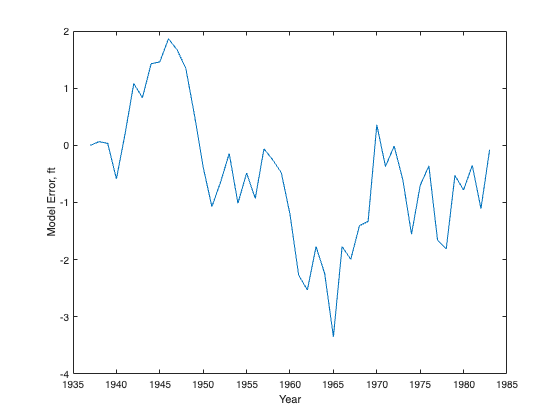

% **Create a figure and plot the error vs time.**
figure
plot(t,Error)
hold on
xlabel("Year")
ylabel("Model Error, ft")

In addition to visually inspecting the error we can calculate some basic statistics of the error distirbution.

% **Use mean() to calculate the mean error. Omit the ; so that the result appears onscreen**
Mean_Error = mean(Error)

Mean_Error = -0.5314

Ideally your errors will be evenly distributed around the data. Are they? If not, what sort of bias do they have (over or under estimating)?


% **Use quantile(error, [0.05, 0.50, 0.95]) to estimate a non-parametric 95% confidence
% interval and median for our model. Omit the ; so that the result appears onscreen**
Error_Distribution = quantile(Error, [0.05, 0.50, 0.95])

Error_Distribution =    -2.3108   -0.4859    1.4902


What are the assumptions of using these values as an error estimate?

## Run an experiment:

Once you are satisfied that your model is working well:

    1.    How long would it take the lake to return to pre-diversion elevations (steady-state) if the court orderd no more diversions in 2017? You can copy and paste lines of code from your model above into the window below or save a copy of this document and then modify them to solve this new problem.

            a.    Change your time vector to extend from 2017 to 2500. (Ideally you will also re-initalize your model vectors to the appropriate length).

            b.    Change your initial conditions (lake volume and elevation) to the 2017 values.

            c.    Replace the vector elements in the current model equation with their averages (or zero for diversion). The most efficient way to do this is to create new variables outside of the loop and set them equal to the mean of each flux or rate and then use these new variables in your equation.

            d.    When does the lake exceed 95% of steady state volume (challenge: find the exact year using the *find* command)? What are the steady-state inflows, outflows, volume and elevation (you can check these by querying the value of each variable at the end of your model run)?

            e.    What is average residence time of water in Mono Lake for your model?

% We will use a constant time interval, dt (start with dt = 1 (year)).
dt = 1;

% Set starting time - ts (start with a model running from 1937 to 1983).
ts = 2017;

% Set ending time - tf (start with a model running from 1937 to 1983).
tf = 2500;

% Define a vector of time steps, t, for the model using first:interval:last syntax.
% Your model should run from ts to tf in steps of dt.
t = ts:dt:tf;
t = t';

% Read in Vorster measured data using xlsread
    % All data are in cells B2:B48, The individal sheets contain the following data:
    % 1. Elevation [feet above msl], 2. Volume [Acre-Feet], 3. Area [Acres],
    % 4. Gauged stream [flow, Acre-Feet per Year], 5. Diversion [flow, Acre-Feet per Year]
    % 6. Ungauged [flow, Acre-Feet per Year], 7. Precipitation [rate, Feet per Year],
    % 8. Evaporation [rate, Feet per Year].

% read in data sets that we will use in the model.
    % The MATLAB code is given for the Gauged Stream flows (Q_gauged).
    Q_gauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Gauged stream', 'datarange','B2:B48');
    avgGauged = ones(size(t)).*mean(Q_gauged);

    
    % ** Copy and modify for Diversion (Q_diversion), Unguaged (Q_ungauged)
    % streams, Precipitation (P_rate) and Evaporation (E_rate) rates.**
    Q_diversion = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Diversion', 'datarange','B2:B48');
    avgDiversion = ones(size(t)).*mean(Q_diversion);
    Q_ungauged = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Ungauged', 'datarange','B2:B48');
    avgUngauged = ones(size(t)).*mean(Q_ungauged);
    P_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Precipitation', 'datarange','B2:B48');
    avgPrate = ones(size(t)).*mean(P_rate);
    E_rate = readmatrix('Mono_Lake_Flows_1937-1983.xlsx', 'Sheet', 'Evaporation', 'datarange','B2:B48');
    avgErate = ones(size(t)).*mean(E_rate);


% Read in the Vorster lake survey data for volume conversions
    % Columns: 1. Volume (acre-ft), 2. Area (acre), 3. Elevation (ft above msl)
    % We'll read in all the numeric values so we can use this simple syntax
    Survey = readmatrix('Mono_Lake_Survey.xlsx');

% Read in the historic lake elevation data from the MLC (years in column A, elevations in B,
% all rows 2 to 167. Use xlsread to read appropriate columns into 2 variables: 
% YR_measured and Z_measured
YR_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'A2:A173');
Z_measured = readmatrix('MLC_Lake_Levels_1850-2021.xlsx', 'datarange', 'B2:B173');

% The MLC data are reported in calendar years, while Vorster data are
% reported in water years. ** add one to the MLC YR_measured to make the
% data sets conistent**
YR_measured = YR_measured + 1;


% Set the inital lake elevation (Z0) based on starting year
% we'll use logical indexing, which is very handy for this sort of task.
Z0 = Z_measured(YR_measured==ts); % feet above msl

% We'll use the lake survey data and linear interpolation to estimate the
% initial water volume (V0) from the initial lake elevation (Z0)
V0 = interp1(Survey(:,3), Survey(:,1), Z0);

% ** Define variables to store your results: V_Model for Lake Volume and
% Z_Model for elevation at each time step. Use zeros and size to make a vector of
% zeros the same size as your time vector.**
V_Model = zeros (size(t));
Z_Model = zeros (size(t));

% ** Set the first value of V_Model and Z_Model equal to the intial condition for each variable (V0, Z0).**
V_Model(1) = V0;
Z_Model(1) = Z0;

% Forward Euler solution. Our solution will step through the time steps calculating
% the next solution from the current solution.

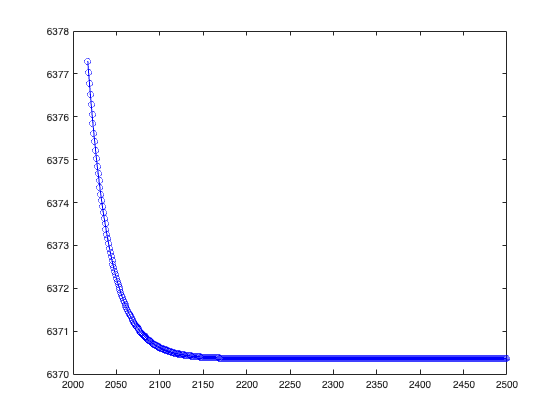

% **define a for loop that steps from n=1 to one less than the number of time steps.**
for n = 1:length(t)-1
    % Calculations within loop:

    
    % Estimate area (acres) from volume (acre-ft) using linear interpolation
    % We'll interpolate the area based on our modeled volume using interp1
    LakeArea = interp1(Survey(:,1), Survey(:,2), V_Model(n));
    
    % Later lake area is coming up as NAN - what to do with this?
    
    % Estimate evaporation **and precipitation** fluxes from lake area and rates
    Q_Evap = avgErate(n) .* LakeArea;
    Q_Precip = avgPrate(n) .* LakeArea;
    
    % ** Add equation for Euler method. Store results in the next element (n+1) of V_Model**
    V_Model(n+1) = V_Model(n) + ((avgGauged(n)+avgUngauged(n)+Q_Precip-Q_Evap-avgDiversion(n)) .* dt);
    
    % **Estimate model lake elevation (ft above msl) from model volume (acre-ft) for next
    % time step using linear interpolation (interp 1) and Vorster survey data.**
    Z_Model(n+1) = interp1(Survey(:,1), Survey(:,3), V_Model(n+1));
    
% **define the end of your loop with 'end'**
end

% **plot model results using blue line and circle**
figure
plot (t,Z_Model,'bo-')
hold on

## Turn in your completed script with embedded figures and answers to questions.